# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

T = 1

T = 1

displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;

delta_t = 0.25; % 15 minutes = 0.25 hours
% globalPVCoeff = 2.3;
globalPVCoeff = 1.0;
% lambdaVals = generateLoadProfile(T, 1.0, 1.1, 'upwards')
lambdaVals = generateLoadProfile(T, 1.0, 1.0, 'upwards')

lambdaVals = 1

loadVals = lambdaVals*3

loadVals = 3

% pvCoeffVals = globalPVCoeff*generatePVProfile(T, 0.8, 1.2, 0.9)
pvCoeffVals = globalPVCoeff*generatePVProfile(T, 1.0, 1.0, 1.0)

pvCoeffVals = 1


if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
end

if strcmp(systemName, "ieee123")
    N = 128;
else
    error("Unknown Power System")
end

% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.KV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;

simInfo = struct();
simInfo.objFunction = objFunction;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.alg.temporal = "BruteForce";
macroItrMax = 10; % Max no. of permissible iterations for optimizing an area
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

Macro-iteration 0: Running OPF for Area 1.


v_parent_Area_1toT = 1.0609

S_childAreas_1toT =      0
     0


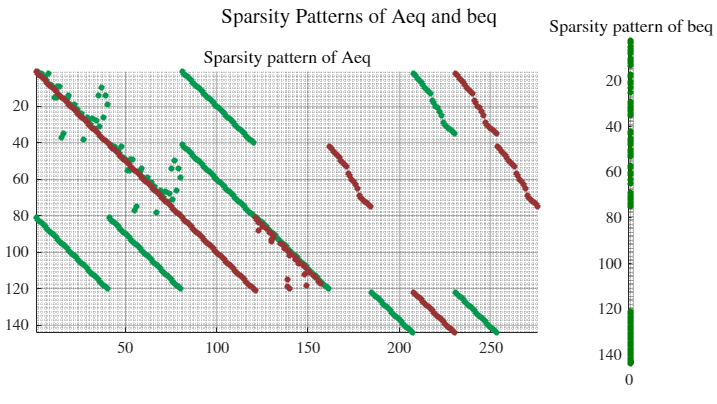

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.432557e-06     6.388e-03     1.000e+00     4.064e-01     7.599e-02  
    2         831    8.047604e-05     8.486e-08     1.000e+00     1.052e-02     6.021e-03  
    3        1108    8.034297e-05     2.518e-08     1.000e+00     3.672e-04     1.577e-04  
    4        1385    7.968257e-05     6.184e-07     1.000e+00     1.820e-03     1.506e-04  
    5        1662    7.667846e-05     1.412e-05     1.000e+00     8.697e-03     1.167e-04  
    6        1939    7.497046e-05     1.054e-05     1.000e+00     7.532e-03     9.820e-05  
    7        2216    7.483780e-05     4.566e-07     1.000e+00     1.779e-03     9.435e-05  
    8        2493    7.379269e-05     4.195e-06     1.000e+00     5.351e-03     8.

Macro-iteration 0: Running OPF for Area 2.


v_parent_Area_1toT = 1.0609

S_childAreas_1toT = 0

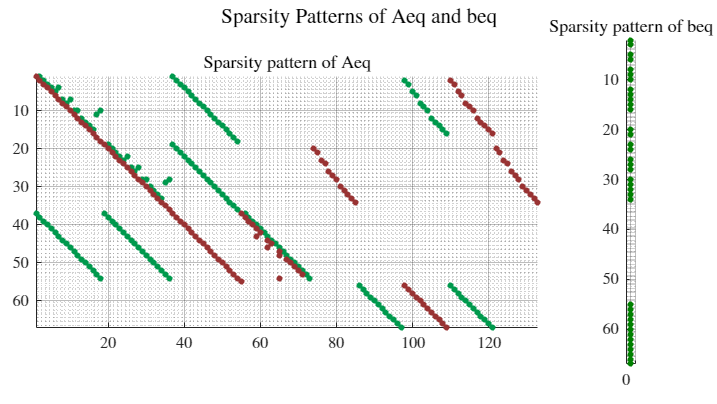

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     1.415e-02  
    1         268    3.208230e-06     3.246e-03     1.000e+00     2.929e-01     6.090e-02  
    2         402    8.115868e-05     1.592e-08     1.000e+00     6.486e-03     3.071e-03  
    3         536    8.115918e-05     2.220e-16     1.000e+00     3.644e-08     3.661e-09  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 3.661461e-09,
is less than options.OptimalityTolerance = 1.000000e

Macro-iteration 0: Running OPF for Area 3.


v_parent_Area_1toT = 1.0609


S_childAreas_1toT =

  0×1 empty double column vector



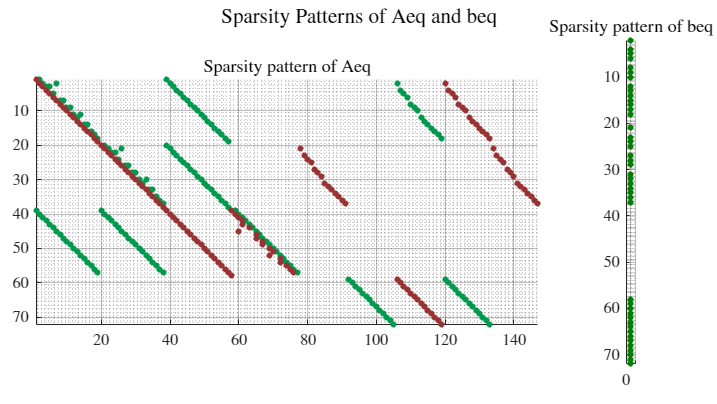

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    4.404061e-06     7.285e-03     1.000e+00     3.253e-01     7.550e-02  
    2         444    7.772806e-05     2.767e-08     1.000e+00     1.341e-02     6.889e-03  
    3         592    7.772836e-05     2.220e-16     1.000e+00     5.431e-08     5.293e-09  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.292920e-09,
is less than options.OptimalityTolerance = 1.000000e

Macro-iteration 0: Running OPF for Area 4.


v_parent_Area_1toT = 1.0609


S_childAreas_1toT =

  0×1 empty double column vector



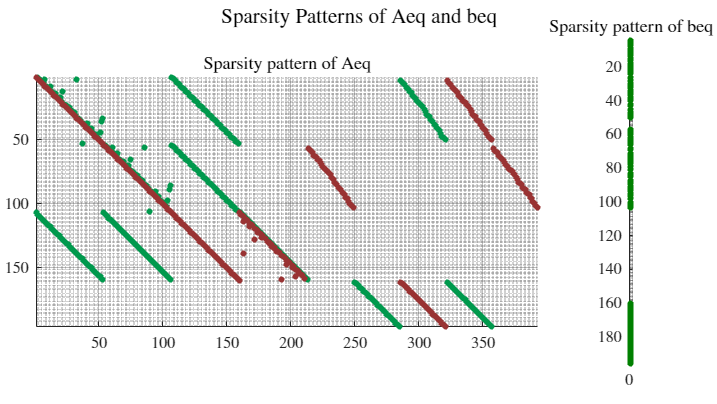

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    8.311326e-06     3.747e-02     1.000e+00     6.859e-01     1.943e-01  
    2        1182    7.081104e-04     2.143e-06     1.000e+00     7.202e-02     3.501e-02  
    3        1576    7.075266e-04     7.385e-08     1.000e+00     7.854e-04     2.627e-04  
    4        1970    7.049083e-04     1.412e-06     1.000e+00     3.442e-03     2.440e-04  
    5        2364    6.943108e-04     2.543e-05     1.000e+00     1.506e-02     2.582e-04  
    6        2758    6.917796e-04     8.512e-06     1.000e+00     8.665e-03     6.025e-04  
    7        3152    6.893518e-04     7.557e-06     1.000e+00     7.980e-03     3.288e-04  
    8        3546    6.894236e-04     1.786e-07     1.000e+00     1.210e-03     3.

Macro-iteration 0: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = -5.3946e-25 - 4.6193e-24i

S12_intoChild_1toT = 0.0551 + 0.0150i

delta_S12_1toT = -0.0551 - 0.0150i

v_parentSide_1toT = 1.0589

v_childSide_1toT = 1.0609

delta_v_1toT = -0.0020

Macro-iteration 0: Current Biggest Residual is 5.707616e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 8.9351e-26 - 6.9467e-25i

S12_intoChild_1toT = 0.0756 + 0.0400i

delta_S12_1toT = -0.0756 - 0.0400i

v_parentSide_1toT = 1.0582

v_childSide_1toT = 1.0609

delta_v_1toT = -0.0027

Macro-iteration 0: Current Biggest Residual is 8.548843e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 9.1293e-26 - 2.1780e-25i

S12_intoChild_1toT = 0.1432 - 0.0367i

delta_S12_1toT = -0.1432 + 0.0367i

v_parentSide_1toT = 1.0582

v_childSide_1toT = 1.0609

delta_v_1toT = -0.0027

Macro-iteration 0: Current Biggest Residual is 1.477841e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 0: Communication between all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 0 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 0 Communication Voltage:****


v1_1toT =     1.0609
    1.0589
    1.0609
    1.0609


***Macro-iteration 0 Communication Power:****


S12_allRelationships_1toT =    0.0551 + 0.0150i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


Communicating between parent Area 1 and child Area 3


***Macro-iteration 0 Communication Voltage:****


v1_1toT =     1.0609
    1.0589
    1.0582
    1.0609


***Macro-iteration 0 Communication Power:****


S12_allRelationships_1toT =    0.0551 + 0.0150i
   0.0756 + 0.0400i
   0.0000 + 0.0000i


Communicating between parent Area 2 and child Area 4


***Macro-iteration 0 Communication Voltage:****


v1_1toT =     1.0609
    1.0589
    1.0582
    1.0582


***Macro-iteration 0 Communication Power:****


S12_allRelationships_1toT =    0.0551 + 0.0150i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Macro-iteration 1: Running OPF for Area 1.


v_parent_Area_1toT = 1.0609

S_childAreas_1toT =    0.0551 + 0.0150i
   0.0756 + 0.0400i


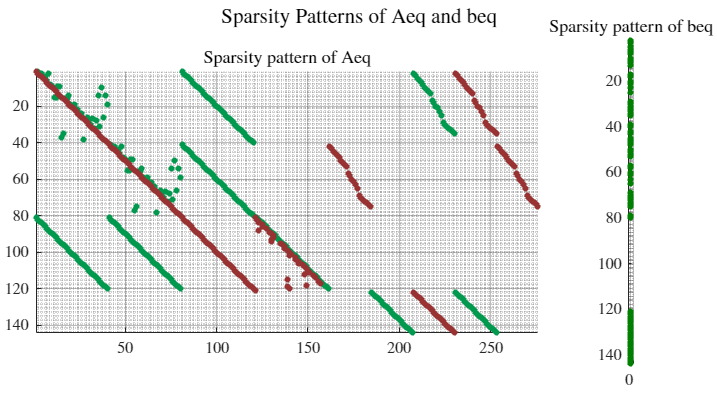

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     7.557e-02     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.432594e-06     4.679e-02     1.000e+00     5.927e-01     2.066e-01  
    2         831    5.998570e-04     1.825e-06     1.000e+00     9.043e-02     4.449e-02  
    3        1108    5.998821e-04     2.755e-15     1.000e+00     3.701e-06     3.583e-07  

Optimization completed: The relative first-order optimality measure, 3.582520e-07,
is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint
violation, 2.754741e-15, is less than opt

Macro-iteration 1: Running OPF for Area 2.


v_parent_Area_1toT = 1.0589

S_childAreas_1toT = 0.1432 - 0.0367i

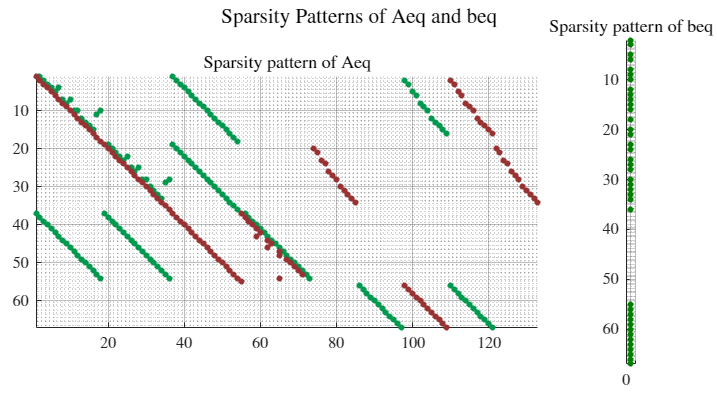

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.432e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    3.208269e-06     3.934e-02     1.000e+00     5.503e-01     1.981e-01  
    2         402    6.660578e-04     7.266e-07     1.000e+00     8.826e-02     3.739e-02  
    3         536    6.660077e-04     1.282e-08     1.000e+00     1.986e-04     1.112e-04  
    4         670    6.659196e-04     6.504e-08     1.000e+00     4.993e-04     1.319e-04  
    5         804    6.654995e-04     1.551e-06     1.000e+00     2.438e-03     1.152e-04  
    6         939    6.644116e-04     5.962e-09     1.000e+00     1.007e-02     4.542e-05  
    7        1073    6.643254e-04     3.965e-07     1.000e+00     1.247e-03     1.879e-04  
    8        1208    6.641323e-04     1.847e-09     1.000e+00     5.321e-03     4.

Macro-iteration 1: Running OPF for Area 3.


v_parent_Area_1toT = 1.0582


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     5.818e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    4.404061e-06     7.285e-03     1.000e+00     3.156e-01     7.550e-02  
    2         444    7.791728e-05     2.781e-08     1.000e+00     1.344e-02     6.906e-03  
    3         592    7.791758e-05     2.220e-16     1.000e+00     5.473e-08     5.334e-09  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.333807e-09,
is less than options.OptimalityTolerance = 1.000000e

Macro-iteration 1: Running OPF for Area 4.


v_parent_Area_1toT = 1.0582


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    8.311325e-06     3.747e-02     1.000e+00     6.733e-01     1.943e-01  
    2        1182    7.092451e-04     2.168e-06     1.000e+00     7.219e-02     3.509e-02  
    3        1576    7.086710e-04     7.424e-08     1.000e+00     7.794e-04     2.633e-04  
    4        1970    7.060686e-04     1.441e-06     1.000e+00     3.444e-03     2.404e-04  
    5        2364    6.955951e-04     2.578e-05     1.000e+00     1.499e-02     2.405e-04  
    6        2758    6.930511e-04     8.851e-06     1.000e+00     8.747e-03     2.405e-04  
    7        3152    6.908220e-04     7.001e-06     1.000e+00     7.599e-03     3.304e-04  
    8        3546    6.908577e-04     1.788e-07     1.000e+00     1.217e-03     3.

Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.0551 + 0.0150i

S12_intoChild_1toT = 0.1988 - 0.0008i

delta_S12_1toT = -0.1437 + 0.0158i

v_parentSide_1toT = 1.0530

v_childSide_1toT = 1.0589

delta_v_1toT = -0.0059

Macro-iteration 1: Current Biggest Residual is 1.445988e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.0756 + 0.0400i

S12_intoChild_1toT = 0.0756 + 0.0400i

delta_S12_1toT = -6.8520e-08 - 2.6465e-07i

v_parentSide_1toT = 1.0497

v_childSide_1toT = 1.0582

delta_v_1toT = -0.0085

Macro-iteration 1: Current Biggest Residual is 8.524504e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1432 - 0.0367i

S12_intoChild_1toT = 0.1432 - 0.0367i

delta_S12_1toT = -1.3420e-06 - 8.6337e-06i

v_parentSide_1toT = 1.0526

v_childSide_1toT = 1.0582

delta_v_1toT = -0.0056

Macro-iteration 1: Current Biggest Residual is 5.590932e-03 at index 2.


Macro-iteration 1: Communication between all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0530
    1.0582
    1.0582


***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0530
    1.0497
    1.0582


***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0530
    1.0497
    1.0526


***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Macro-iteration 2: Running OPF for Area 1.


v_parent_Area_1toT = 1.0609

S_childAreas_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     1.988e-01     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.432617e-06     1.251e-01     1.000e+00     8.671e-01     3.504e-01  
    2         831    1.454128e-03     1.087e-05     1.000e+00     2.516e-01     1.191e-01  
    3        1108    1.454258e-03     9.140e-14     1.000e+00     2.244e-05     2.094e-06  
    4        1385    1.454258e-03     2.776e-17     1.000e+00     1.861e-13     5.787e-11  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.786622e-11,
is less than 

Macro-iteration 2: Running OPF for Area 2.


v_parent_Area_1toT = 1.0530

S_childAreas_1toT = 0.1432 - 0.0367i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.432e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    3.208269e-06     3.932e-02     1.000e+00     5.399e-01     1.982e-01  
    2         402    6.694885e-04     6.764e-07     1.000e+00     8.875e-02     3.759e-02  
    3         536    6.694511e-04     8.524e-09     1.000e+00     1.748e-04     9.069e-05  
    4         670    6.693562e-04     8.931e-08     1.000e+00     5.792e-04     1.189e-04  
    5         804    6.689101e-04     2.103e-06     1.000e+00     2.811e-03     1.002e-04  
    6         939    6.680681e-04     4.570e-09     1.000e+00     8.858e-03     6.110e-05  
    7        1073    6.679967e-04     3.446e-07     1.000e+00     1.150e-03     6.844e-05  
    8        1208    6.678404e-04     1.267e-09     1.000e+00     4.888e-03     4.

Macro-iteration 2: Running OPF for Area 3.


v_parent_Area_1toT = 1.0497


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    4.404061e-06     7.285e-03     1.000e+00     2.864e-01     7.550e-02  
    2         444    7.851636e-05     2.827e-08     1.000e+00     1.355e-02     6.963e-03  
    3         592    7.851667e-05     2.220e-16     1.000e+00     5.608e-08     5.466e-09  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.465544e-09,
is less than options.OptimalityTolerance = 1.000000e

Macro-iteration 2: Running OPF for Area 4.


v_parent_Area_1toT = 1.0526


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    8.311324e-06     3.747e-02     1.000e+00     6.482e-01     1.943e-01  
    2        1182    7.116936e-04     2.220e-06     1.000e+00     7.256e-02     3.528e-02  
    3        1576    7.111381e-04     7.507e-08     1.000e+00     7.680e-04     2.647e-04  
    4        1970    7.085630e-04     1.504e-06     1.000e+00     3.451e-03     2.328e-04  
    5        2364    6.983128e-04     2.657e-05     1.000e+00     1.488e-02     2.328e-04  
    6        2758    6.957168e-04     9.731e-06     1.000e+00     8.992e-03     6.254e-04  
    7        3152    6.939306e-04     5.734e-06     1.000e+00     6.733e-03     3.610e-04  
    8        3546    6.938941e-04     1.738e-07     1.000e+00     1.212e-03     3.

Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1988 - 0.0008i

S12_intoChild_1toT = 0.1988 - 0.0008i

delta_S12_1toT = -4.7903e-06 + 1.5283e-05i

v_parentSide_1toT = 1.0503

v_childSide_1toT = 1.0530

delta_v_1toT = -0.0027

Macro-iteration 2: Current Biggest Residual is 2.745098e-03 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.0756 + 0.0400i

S12_intoChild_1toT = 0.0756 + 0.0400i

delta_S12_1toT = -4.7807e-07 - 1.0990e-06i

v_parentSide_1toT = 1.0469

v_childSide_1toT = 1.0497

delta_v_1toT = -0.0027

Macro-iteration 2: Current Biggest Residual is 2.740693e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1432 - 0.0367i

S12_intoChild_1toT = 0.1432 - 0.0368i

delta_S12_1toT = -3.2006e-06 + 5.2245e-05i

v_parentSide_1toT = 1.0467

v_childSide_1toT = 1.0526

delta_v_1toT = -0.0059

Macro-iteration 2: Current Biggest Residual is 5.906874e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 2: Communication between all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0514
    1.0497
    1.0526


***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.1916 - 0.0000i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0514
    1.0482
    1.0526


***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.1916 - 0.0000i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0514
    1.0482
    1.0488


***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.1916 - 0.0000i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Macro-iteration 3: Running OPF for Area 1.


v_parent_Area_1toT = 1.0609

S_childAreas_1toT =    0.1916 - 0.0000i
   0.0756 + 0.0400i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     1.916e-01     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.432616e-06     1.202e-01     1.000e+00     8.519e-01     3.432e-01  
    2         831    1.399911e-03     1.007e-05     1.000e+00     2.412e-01     1.144e-01  
    3        1108    1.400032e-03     7.218e-14     1.000e+00     2.076e-05     1.941e-06  
    4        1385    1.400032e-03     2.220e-16     1.000e+00     1.474e-13     5.785e-11  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.785079e-11,
is less than 

Macro-iteration 3: Running OPF for Area 2.


v_parent_Area_1toT = 1.0514

S_childAreas_1toT = 0.1432 - 0.0367i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.432e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    3.208269e-06     3.932e-02     1.000e+00     5.372e-01     1.982e-01  
    2         402    6.704681e-04     6.635e-07     1.000e+00     8.888e-02     3.764e-02  
    3         536    6.704344e-04     7.402e-09     1.000e+00     1.686e-04     8.451e-05  
    4         670    6.703361e-04     1.008e-07     1.000e+00     6.134e-04     1.129e-04  
    5         804    6.698763e-04     2.362e-06     1.000e+00     2.969e-03     9.358e-05  
    6         939    6.691083e-04     4.114e-09     1.000e+00     8.440e-03     5.806e-05  
    7        1073    6.690398e-04     3.369e-07     1.000e+00     1.133e-03     6.292e-05  
    8        1208    6.688921e-04     1.161e-09     1.000e+00     4.806e-03     3.

Macro-iteration 3: Running OPF for Area 3.


v_parent_Area_1toT = 1.0482


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    4.404061e-06     7.285e-03     1.000e+00     2.815e-01     7.550e-02  
    2         444    7.862224e-05     2.835e-08     1.000e+00     1.357e-02     6.973e-03  
    3         592    7.862255e-05     2.220e-16     1.000e+00     5.632e-08     5.489e-09  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.488871e-09,
is less than options.OptimalityTolerance = 1.000000e

Macro-iteration 3: Running OPF for Area 4.


v_parent_Area_1toT = 1.0488


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    8.311323e-06     3.747e-02     1.000e+00     6.318e-01     1.943e-01  
    2        1182    7.134549e-04     2.257e-06     1.000e+00     7.282e-02     3.541e-02  
    3        1576    7.129112e-04     7.564e-08     1.000e+00     7.608e-04     2.657e-04  
    4        1970    7.103505e-04     1.549e-06     1.000e+00     3.459e-03     2.295e-04  
    5        2364    7.002272e-04     2.717e-05     1.000e+00     1.484e-02     3.817e-04  
    6        2758    6.975712e-04     1.052e-05     1.000e+00     9.231e-03     6.486e-04  
    7        3152    6.961155e-04     4.795e-06     1.000e+00     6.073e-03     3.906e-04  
    8        3546    6.960319e-04     1.687e-07     1.000e+00     1.199e-03     3.

Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1916 - 0.0000i

S12_intoChild_1toT = 0.1988 - 0.0008i

delta_S12_1toT = -0.0072 + 0.0008i

v_parentSide_1toT = 1.0504

v_childSide_1toT = 1.0514

delta_v_1toT = -9.8060e-04

Macro-iteration 3: Current Biggest Residual is 7.235257e-03 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.0756 + 0.0400i

S12_intoChild_1toT = 0.0756 + 0.0400i

delta_S12_1toT = -1.7407e-07 - 4.7991e-07i

v_parentSide_1toT = 1.0471

v_childSide_1toT = 1.0482

delta_v_1toT = -0.0011

Macro-iteration 3: Current Biggest Residual is 1.110352e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1432 - 0.0367i

S12_intoChild_1toT = 0.1432 - 0.0367i

delta_S12_1toT = -3.2695e-06 - 4.4070e-05i

v_parentSide_1toT = 1.0451

v_childSide_1toT = 1.0488

delta_v_1toT = -0.0037

Macro-iteration 3: Current Biggest Residual is 3.677195e-03 at index 2.


Macro-iteration 3: Communication between all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0505
    1.0482
    1.0488


***Macro-iteration 3 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0505
    1.0471
    1.0488


***Macro-iteration 3 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0505
    1.0471
    1.0459


***Macro-iteration 3 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Macro-iteration 4: Running OPF for Area 1.


v_parent_Area_1toT = 1.0609

S_childAreas_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     1.988e-01     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.432617e-06     1.251e-01     1.000e+00     8.671e-01     3.504e-01  
    2         831    1.454177e-03     1.087e-05     1.000e+00     2.516e-01     1.191e-01  
    3        1108    1.454308e-03     9.123e-14     1.000e+00     2.245e-05     2.094e-06  
    4        1385    1.454308e-03     5.031e-17     1.000e+00     1.772e-13     5.787e-11  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.786616e-11,
is less than 

Macro-iteration 4: Running OPF for Area 2.


v_parent_Area_1toT = 1.0505

S_childAreas_1toT = 0.1432 - 0.0367i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.432e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    3.208269e-06     3.932e-02     1.000e+00     5.358e-01     1.982e-01  
    2         402    6.709988e-04     6.566e-07     1.000e+00     8.896e-02     3.768e-02  
    3         536    6.709668e-04     6.916e-09     1.000e+00     1.656e-04     8.169e-05  
    4         670    6.708677e-04     1.053e-07     1.000e+00     6.260e-04     1.095e-04  
    5         804    6.704053e-04     2.462e-06     1.000e+00     3.027e-03     9.015e-05  
    6         939    6.696730e-04     3.865e-09     1.000e+00     8.226e-03     5.647e-05  
    7        1073    6.696060e-04     3.323e-07     1.000e+00     1.124e-03     5.989e-05  
    8        1208    6.694623e-04     1.108e-09     1.000e+00     4.761e-03     3.

Macro-iteration 4: Running OPF for Area 3.


v_parent_Area_1toT = 1.0471


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    4.404061e-06     7.285e-03     1.000e+00     2.783e-01     7.550e-02  
    2         444    7.869441e-05     2.841e-08     1.000e+00     1.359e-02     6.979e-03  
    3         592    7.869472e-05     2.220e-16     1.000e+00     5.648e-08     5.505e-09  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.505101e-09,
is less than options.OptimalityTolerance = 1.000000e

Macro-iteration 4: Running OPF for Area 4.


v_parent_Area_1toT = 1.0459


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    8.311323e-06     3.747e-02     1.000e+00     6.201e-01     1.943e-01  
    2        1182    7.148093e-04     2.285e-06     1.000e+00     7.302e-02     3.550e-02  
    3        1576    7.142743e-04     7.608e-08     1.000e+00     7.556e-04     2.665e-04  
    4        1970    7.117243e-04     1.584e-06     1.000e+00     3.465e-03     2.305e-04  
    5        2364    7.017087e-04     2.755e-05     1.000e+00     1.478e-02     2.231e-04  
    6        2758    6.989096e-04     1.159e-05     1.000e+00     9.605e-03     6.766e-04  
    7        3152    6.977872e-04     3.894e-06     1.000e+00     5.418e-03     4.114e-04  
    8        3546    6.976727e-04     1.567e-07     1.000e+00     1.144e-03     3.

Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1988 - 0.0008i

S12_intoChild_1toT = 0.1988 - 0.0008i

delta_S12_1toT = -3.9453e-06 + 3.1026e-06i

v_parentSide_1toT = 1.0503

v_childSide_1toT = 1.0505

delta_v_1toT = -2.3358e-04

Macro-iteration 4: Current Biggest Residual is 2.335777e-04 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.0756 + 0.0400i

S12_intoChild_1toT = 0.0756 + 0.0400i

delta_S12_1toT = -1.2871e-08 - 1.5165e-07i

v_parentSide_1toT = 1.0469

v_childSide_1toT = 1.0471

delta_v_1toT = -2.3323e-04

Macro-iteration 4: Current Biggest Residual is 2.332334e-04 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1432 - 0.0367i

S12_intoChild_1toT = 0.1432 - 0.0367i

delta_S12_1toT = -2.4314e-06 - 2.6581e-05i

v_parentSide_1toT = 1.0442

v_childSide_1toT = 1.0459

delta_v_1toT = -0.0017

Macro-iteration 4: Current Biggest Residual is 1.668496e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 4: Communication between all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0503
    1.0471
    1.0459


***Macro-iteration 4 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0503
    1.0469
    1.0459


***Macro-iteration 4 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0503
    1.0469
    1.0445


***Macro-iteration 4 Communication Power:****


S12_allRelationships_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i
   0.1432 - 0.0367i


Macro-iteration 5: Running OPF for Area 1.


v_parent_Area_1toT = 1.0609

S_childAreas_1toT =    0.1988 - 0.0008i
   0.0756 + 0.0400i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     1.988e-01     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.432617e-06     1.251e-01     1.000e+00     8.671e-01     3.504e-01  
    2         831    1.454203e-03     1.087e-05     1.000e+00     2.516e-01     1.191e-01  
    3        1108    1.454333e-03     9.132e-14     1.000e+00     2.245e-05     2.094e-06  
    4        1385    1.454333e-03     2.230e-17     1.000e+00     1.802e-13     2.911e-11  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 2.910995e-11,
is less than 

Macro-iteration 5: Running OPF for Area 2.


v_parent_Area_1toT = 1.0503

S_childAreas_1toT = 0.1432 - 0.0367i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.432e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    3.208269e-06     3.932e-02     1.000e+00     5.355e-01     1.982e-01  
    2         402    6.711245e-04     6.551e-07     1.000e+00     8.898e-02     3.768e-02  
    3         536    6.710929e-04     6.836e-09     1.000e+00     1.650e-04     8.121e-05  
    4         670    6.709938e-04     1.057e-07     1.000e+00     6.269e-04     1.089e-04  
    5         804    6.705322e-04     2.469e-06     1.000e+00     3.031e-03     8.956e-05  
    6         939    6.698066e-04     3.812e-09     1.000e+00     8.184e-03     5.619e-05  
    7        1073    6.697400e-04     3.308e-07     1.000e+00     1.121e-03     5.938e-05  
    8        1208    6.695971e-04     1.095e-09     1.000e+00     4.749e-03     3.

Macro-iteration 5: Running OPF for Area 3.


v_parent_Area_1toT = 1.0469


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    4.404061e-06     7.285e-03     1.000e+00     2.776e-01     7.550e-02  
    2         444    7.870857e-05     2.842e-08     1.000e+00     1.359e-02     6.981e-03  
    3         592    7.870888e-05     2.220e-16     1.000e+00     5.651e-08     5.508e-09  

Feasible point with lower objective function value found.


Optimization completed: The relative first-order optimality measure, 5.508300e-09,
is less than options.OptimalityTolerance = 1.000000e

Macro-iteration 5: Running OPF for Area 4.


v_parent_Area_1toT = 1.0445


S_childAreas_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    8.311322e-06     3.747e-02     1.000e+00     6.149e-01     1.943e-01  
    2        1182    7.154380e-04     2.297e-06     1.000e+00     7.311e-02     3.555e-02  
    3        1576    7.149069e-04     7.628e-08     1.000e+00     7.533e-04     2.668e-04  
    4        1970    7.123614e-04     1.600e-06     1.000e+00     3.468e-03     2.310e-04  
    5        2364    7.024174e-04     2.760e-05     1.000e+00     1.472e-02     2.211e-04  
    6        2758    6.995070e-04     1.229e-05     1.000e+00     9.847e-03     6.934e-04  
    7        3152    6.985499e-04     3.492e-06     1.000e+00     5.105e-03     3.924e-04  
    8        3546    6.984428e-04     1.416e-07     1.000e+00     1.049e-03     2.

Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1988 - 0.0008i

S12_intoChild_1toT = 0.1988 - 0.0008i

delta_S12_1toT = -2.7505e-06 + 1.2255e-06i

v_parentSide_1toT = 1.0503

v_childSide_1toT = 1.0503

delta_v_1toT = -3.4427e-05

Macro-iteration 5: Current Biggest Residual is 3.442740e-05 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.0756 + 0.0400i

S12_intoChild_1toT = 0.0756 + 0.0400i

delta_S12_1toT = 7.9915e-08 + 3.7309e-08i

v_parentSide_1toT = 1.0469

v_childSide_1toT = 1.0469

delta_v_1toT = -3.4389e-05

Macro-iteration 5: Current Biggest Residual is 3.438910e-05 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1432 - 0.0367i

S12_intoChild_1toT = 0.1432 - 0.0367i

delta_S12_1toT = -1.1812e-06 - 2.3579e-05i

v_parentSide_1toT = 1.0440

v_childSide_1toT = 1.0445

delta_v_1toT = -5.4654e-04

Macro-iteration 5: Current Biggest Residual is 5.465376e-04 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 5: Communication between all connected areas completed.


MPOPF for Horizon T = 1 Converged in 6 macro-iterations!


if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);
S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
    
while keepRunningIterations
    for Area = 1:numAreas
    % for Area = 1
    % for Area = 2
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr, Area);

        v_parent_Area_1toT = v1_1toT(Area, 1:T)
        S_childAreas_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T)

        if simInfo.macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parent_Area_1toT, S_childAreas_1toT, ...
            lambdaVals, pvCoeffVals, time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging);

        macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr, Area)
        areaInfo = sysInfo.Area{Area};
        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;

        P_Area_1toT = reshape(xVals_Area(areaInfo.indices_Pij), m_Area, T); %m_Areax1
        Q_Area_1toT = reshape(xVals_Area(areaInfo.indices_Qij), m_Area, T); %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = reshape(xVals_Area(areaInfo.indices_vAllj), N_Area, T); %N_Areax1
        
        % row_parentBus = getIndicesT(areaInfo.indices_Pij, 1);
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;   % Storing all the S flow of the Area
    
        % keyboard
    end
    
    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr);
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T)
            S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T)
    
            delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T)
            v_childSide_1toT = v1_1toT(chAr, 1:T)
    
            delta_v_1toT = v_parentSide_1toT - v_childSide_1toT
    
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            % [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            % [row, col] = ind2sub(size(currentMaxResidual_1toT), lin_idx);
            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr, currentMaxResidual_1toT, row);

            % myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at (%d, %d).\n", macroItr, currentMaxResidual_1toT, row, col);
            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
    
        end
        
        myfprintf(true, "Macro-iteration %d: Communication between all connected areas completed.\n", macroItr);
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;
                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr-1, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T)

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr-1, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T)
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T)
                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T)
    
                end
    
            end

            simInfo.macroItr = simInfo.macroItr + 1;

        end

    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

if fileOpenedFlag
    fclose(fid);
end
grandTotalTime = toc(start)

grandTotalTime = 105.9198